# Robótica- Lab4

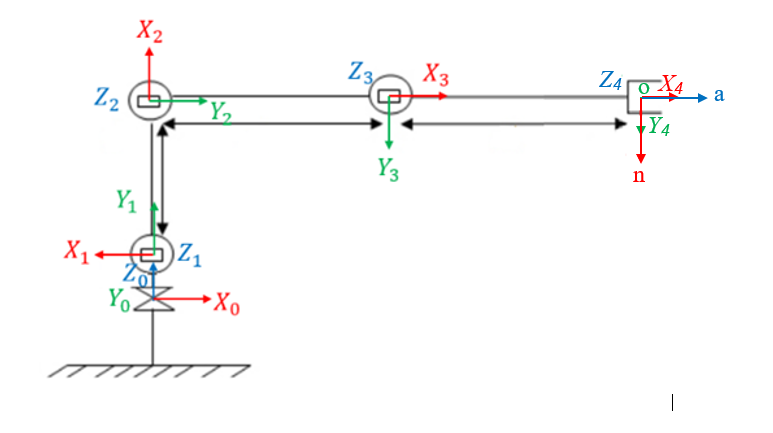

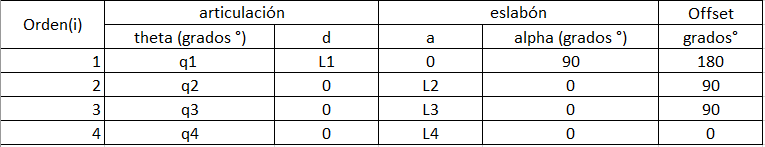

(Para que se cumpla la convención noa se hace una matriz de transformacion homogenea relacionando el frame 4 con el TCP que es el que se quiere que tenga dicha convención)

clc
clear
L1_4= 4.6; %%cm
L2_4= 10.7;
L3_4= 10.7;
L4_4= 9.5;
L(1) = Link('revolute', 'd' , L1_4 , 'a' , 0 , 'alpha' , pi/2 , 'offset' , pi , 'qlim' , [0 2*pi] ); %%pi

Unrecognized function or variable 'Link'.

L(2) = Link('revolute', 'd' , 0 , 'a' , L2_4,'alpha' , 0 , 'offset' , pi/2 , 'qlim' , [0 2*pi] );     %%pi
L(3) = Link('revolute', 'd' , 0, 'a' , L3_4 ,'alpha' , 0 , 'offset' , pi/2 , 'qlim' , [0 2*pi] );      %%0
L(4) = Link('revolute', 'd' , 0 , 'a' , L4_4 , 'alpha' , 0 , 'offset' , 0 , 'qlim' , [0 2*pi] );  %%pi/2

T_Tool_4=rt2tr(rotx(90,"deg")*roty(90,"deg"),[0 0 0]')
Robot4 = SerialLink(L,'name','Robot_4','tool',T_Tool_4)

syms L1 L2 L3 L4 TH1 TH2 TH3 TH4 
T10_4 = calculaMTH(TH1+180,L1,0,90) %%(theta,d,a,alpha)

T21_4 = calculaMTH(TH2+90,0,L2,0)

T32_4 = calculaMTH(TH3+90,0,L3,0)

T43_4 = calculaMTH(TH4,0,L4,0)



Ahora se obtiene el modelo geométrico directo en base a las MTH con las que se cuentan:

T40_4 = T10_4*T21_4*T32_4*T43_4*T_Tool_4

Teniendo el modelo geométrico directo y con los valores dados por el ejercicio es posible calcular la posición y orientación de la herramienta con respecto al marco de referencia base.

T40Subs_4_H = double(subs(T40_4,[L1 L2 L3 L4 TH1 TH2 TH3 TH4 ],[L1_4 L2_4 L3_4 L4_4 0 0 0 0]))
T40Subs_4_1 = double(subs(T40_4,[L1 L2 L3 L4 TH1 TH2 TH3 TH4 ],[L1_4 L2_4 L3_4 L4_4 -25 15 -20 20]))
T40Subs_4_2 = double(subs(T40_4,[L1 L2 L3 L4 TH1 TH2 TH3 TH4 ],[L1_4 L2_4 L3_4 L4_4 35 -35 30 -30]))
T40Subs_4_3 = double(subs(T40_4,[L1 L2 L3 L4 TH1 TH2 TH3 TH4 ],[L1_4 L2_4 L3_4 L4_4 -85 20 -55 17]))
T40Subs_4_4 = double(subs(T40_4,[L1 L2 L3 L4 TH1 TH2 TH3 TH4 ],[L1_4 L2_4 L3_4 L4_4 -80 35 -55 45]))

postura_ej4Eul_H = [T40Subs_4_H(1:3,4);tr2eul(T40Subs_4_H,'deg')']
postura_ej4Eul_1 = [T40Subs_4_1(1:3,4);tr2eul(T40Subs_4_1,'deg')']
postura_ej4Eul_2 = [T40Subs_4_2(1:3,4);tr2eul(T40Subs_4_2,'deg')']
postura_ej4Eul_3 = [T40Subs_4_3(1:3,4);tr2eul(T40Subs_4_3,'deg')']
postura_ej4Eul_4 = [T40Subs_4_4(1:3,4);tr2eul(T40Subs_4_4,'deg')']


La orientación en ángulos fijos se obtiene a partir de la función "tr2rpy"

postura_ej4RPY_H = [T40Subs_4_H(1:3,4);tr2rpy(T40Subs_4_H,'deg')']
postura_ej4RPY_1 = [T40Subs_4_1(1:3,4);tr2rpy(T40Subs_4_1,'deg')']
postura_ej4RPY_2 = [T40Subs_4_2(1:3,4);tr2rpy(T40Subs_4_2,'deg')']
postura_ej4RPY_3 = [T40Subs_4_3(1:3,4);tr2rpy(T40Subs_4_3,'deg')']
postura_ej4RPY_4 = [T40Subs_4_4(1:3,4);tr2rpy(T40Subs_4_4,'deg')']

q4_H= [0 0 0 0] ;
q4_1= [-25*pi/180 15*pi/180 -20*pi/180 20*pi/180];
q4_2= [ 35*pi/180 -35*pi/180 30*pi/180 -30*pi/180];
q4_3= [-85*pi/180 20*pi/180 -55*pi/180 17*pi/180];
q4_4= [-80*pi/180 35*pi/180 -55*pi/180 45*pi/180];

Robot4.fkine(q4_H)
Robot4.fkine(q4_1)
Robot4.fkine(q4_2)
Robot4.fkine(q4_3)
Robot4.fkine(q4_4)
 
Robot4.name = 'R4_H';
ws = [-40 40 -40 40 -40 40];
figure()
Robot4.plot(q4_H,'workspace',ws,'noa','jaxes')
view([33.28 26.14])

Robot4.name = 'R4_q1';
figure()
Robot4.plot(q4_1,'workspace',ws,'noa','jaxes')
view([33.28 26.14])

Robot4.name = 'R4_q2';
figure()
Robot4.plot(q4_2,'workspace',ws,'noa','jaxes')
view([33.28 26.14])

Robot4.name = 'R4_q3';
figure()
Robot4.plot(q4_3,'workspace',ws,'noa','jaxes')
view([33.28 26.14])

Robot4.name = 'R4_q4';
figure()
Robot4.plot(q4_4,'workspace',ws,'noa','jaxes')
view([33.28 26.14])

%Robot4.teach()

%Funcion para calcular la MTH segun:

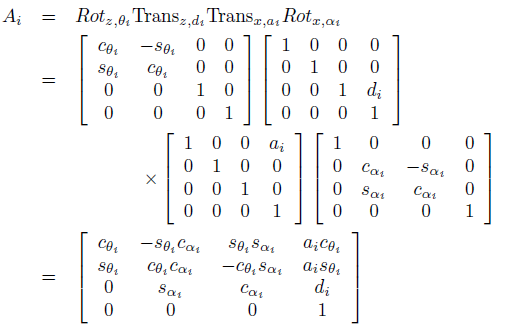

function [Res] = calculaMTH(theta_i,d_i,a_i,alpha_i)
Res = [cosd(theta_i) -sind(theta_i)*cosd(alpha_i) sind(theta_i)*sind(alpha_i) a_i*cosd(theta_i); sind(theta_i) cosd(theta_i)*cosd(alpha_i) -cosd(theta_i)*sind(alpha_i) a_i*sind(theta_i); 0 sind(alpha_i) cosd(alpha_i) d_i; 0 0 0 1];
end